% LQR_I (efecto integrativo)
clc;clear all;close all;
J=0.01;
b=0.1;
K=0.01;
R=1;
L=0.5;
A=[-b/J K/J;-K/L -R/L]

A =   -10.0000    1.0000
   -0.0200   -2.0000


B=[0;1/L]

B =      0
     2


C=[1 0];
D=6;


nx = 2; %nx -> cantidad de estados X
ny = 1; %ny -> canidas de salidas  y, r, 3
nu = 1; %nu -> entradas u

%%Aumentar el sistema en lazo abierto
AOL=[A zeros(nx,ny);-C zeros(ny,ny)]

AOL =   -10.0000    1.0000         0
   -0.0200   -2.0000         0
   -1.0000         0         0


BOL=[B;zeros(ny,nu)]

BOL =      0
     2
     0


QOL=diag([1 1 1000])%  <----- el ultimo valor es la ganancia Ki

QOL =            1           0           0
           0           1           0
           0           0        1000


ROL=0.001;
KOL=lqr(AOL,BOL,QOL,ROL)

KOL = 1.0e+03 *

    0.0905    0.0320   -1.0000


K=KOL(:,1:nx)

K =    90.5306   32.0383


Ki=-KOL(:,(nx+1):end)

Ki = 1.0000e+03

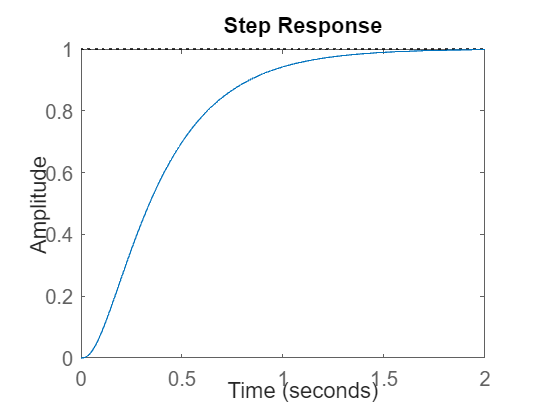


%Cerramos el sistema en lazo Cerardo
ACL=[A-B*K B*Ki;-C zeros(ny,ny)];
BCL=[zeros(nx,ny);eye(ny,ny)];
CCL=[C zeros(ny,ny)];
DCL=0;
GCL=ss(ACL,BCL,CCL,DCL);
step(GCL)